format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

# BOLTE OG SPINDLER

## Alle formler omhandler Metriske ISO gevind - M og MJ(fly ISO 5855)

For en **M10 x 1,5** bolt gælder


$$d=10mm$$



$$p = 1,5mm$$


Hvis der stå **8.8 **på en bolt så slå op i **Table 8-11 **hvis det ikke står der så er

første tal Brudstyrken * 100 MPa her = 800 MPa

andet tal flydespændingen som antal procent * 10% af brudstyrken her = 800 MPa * 0.8

for proof strength se **Table 8-11**

#### Variable

Tabeller og billeder er fra shigleys eller bolt noter

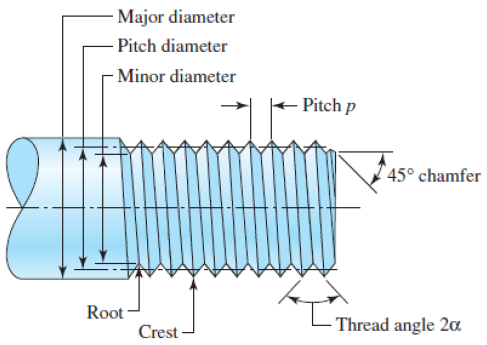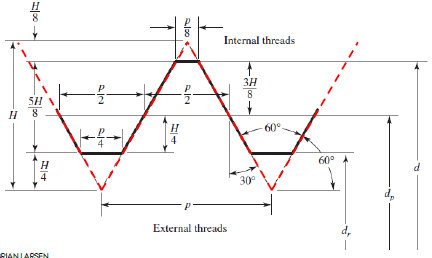

- $d$ - Skaft diameter eller spindeldiameter (major diameter eller nominelle diameter) [mm]

- $d_r$ - Rod diameter (minor diameter) [mm]

- $d_p$ - Pitch diameter  [mm]

- $d_m$ - middeldiameter - kvadratisk gevind(højde og brede af gevind er ens) [mm]

- $d_t$ -  Træk diameteren [mm]

- $d_c$ - Krave diameteren (for krave betydning **se figur 8-7**)) [mm]

- $H$ - Højde af genvind hvis det var trekantet [mm]

- $p$ -  Pitch eller Stigning på gevind (afstand top til top) [mm]

- $n$ - Antal gevind 

- $l$ - Lead(flytning) [mm] pr omdrejning

- $G_d$ - gevinddybde [mm]

- $G_w$ - gevindbrede [mm]

- $A_t$ - Trækspændingsareal (Se **tabel 8-1**) OBS kan også findes med $d_t$ [mm^2]

- $A_d$ - Skaftareal [mm^2]

- $\lambda$ - stigningsvinkel (i dette script angives det i grader)

- $f$ - Friktionskoefficient for gevind

- $f_c$ - Friktionskoefficient for krave (stykke der holde pladen fra gevindet, **se figur 8-7**)

- $v$ - lineær hastighed [mm/s]

- $\omega$ - omdrejningshastighed [1/s]

## Generelt

d =  10;                % Skaft diameter (major diameter)
d_r = 9;                % Rod diameter (minor diameter)
d_p = (d + d_r)/2;      % Pitch diameter
d_t = (d_r + d_p)/2;    % Træk diameteren
p = 1.5;                % Pitch (afstand top til top)
H = sqrt(3)/2 * p;      % Højde af genvind
A_t = pi/4 * d_t^2;     % Trækspændingsareal (Se tabel 8-1) eller udregn med d_t
lamda = 30 %stigningsvinkel i grader til dette script

lamda = 30

## SPINDEL GEOMETRI FOR KVADRATISK GEVIND

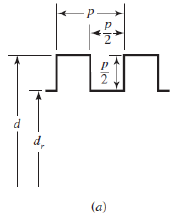

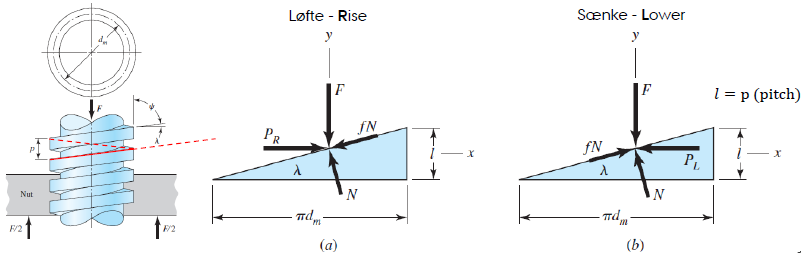

% SPINDEL GEOMETRI FOR KVADRATISK GEVIND
n = 1;                  % antal gevind
l = p * n;              % Lead(flytning) 
G_d = p/2;              % gevinddybde
G_w = p/2;              % gevindbrede
d_r = d - p;            % rod diameter - kvadratisk
d_m = d - p/2; %=d_p    % middeldiameter
d_c = 45;               % Krave diameteren (for krave betydning se figur 8-7))
v = 1;                  % lineær hastighed
omega = v/l * 2*pi      % omdrejningshastighed
F = 100; % * u.N        % Kraften på screw
f = 0.09;               % Friktionskoefficient for gevind
f_c = 0.06;             %Friktionskoefficient for krave (stykke der holde pladen fra gevindet, se figur 8-7)
v = 48;                 % lineær hastighed [mm/s]



% Hæve en last(løfte - rise)
%kraften
P_R = (F * (sind(lambda) + f * cosd(lambda))) /...
    (cosd(lambda) - f * sind(lamda))

% tan(lambda) = l / (pi * d_m) % til at omskrive til moment

% moment
T_R = F * d_m / 2 * ((l + pi * f * d_m) / ...
    (pi * d_m - f * l)) %ligning 8-1


% Hæve en sænke(lower)
%kraften
P_R = (F * (f * cosd(lambda) - sind(lambda))) /...
    (cosd(lambda) + f * sind(lamda))

% tan(lambda) = l / (pi * d_m) % til at omskrive til moment

%moment
T_L = F * d_m / 2 * ((pi * f * d_m - l) / ...
    (pi * d_m + f * l)) % ligning 8-1

%spindel med krave moment (se figur 8-7 for krave betydning)
T_c = F * f_c * d_c / 2 % ligning 8-6


%selv låsende gevind
% Hvis det moment, der skal påføres for at sænke lasten, er positivt, siges gevindet at være
% selvlåsende. Så ligning 8-2 skal resultere i:

% tan(lambda) = l / (pi * d_m)

test = l / (pi * d_m) % eller tan(lambda) %alt efter hvad der er til rådighed

if f > test
    disp("Gevindet er selvlåsende!")
else
    disp("Gevindet er IKKE selvlåsende")
end


%spindel med krave moment (se figur 8-7 for krave betydning)
T_c = F * f_c * d_c / 2 % ligning 8-6


%Bidraget fra kraven regnes med
T_R_tot = T_R + T_c % Total hæve
T_L_tot = T_L + T_c % Total sænke

T_O = F*l/(2*pi) %Power ud uden friktion %ligning g

% Virkningsgrad løft
e = T_O / T_R_tot % = F*l/(2*pi*T_R) % ligning 8-4

% Virkningsgrad sænkning
e = T_O / T_L_tot % = F*l/(2*pi*T_R) % ligning 8-4


% Vinkelhastighed: Læg mærke til af v/l giver omdr/sek. Der skal derfor ganges med 2*pi
omega = v / l * 2 * pi;
omega_ = vpa(omega ,4)

%Effekt for at flytte en spinddel
Power = T_R_tot * omega;
Power_ = unitConvert(vpa(Power,4), u.J)

# FORSPÆNDTE BOLTESAMLINGER

#### Variable

Tabeller og billeder er fra shigleys eller bolt noter

- $d$ - Nominel diameter (skaft)  [mm]

- $d_m$ - Middeldiameter i gevind [mm]

- $d_c$ - Middeldiameter for spændediameteren af  en møtrik [mm]

- $l$ - Klemme længde (regnes kun til midt i underlagets nedre del, se **figur 8-14**) [mm]

- $L$ - Boltlængde  [mm]

- $L_t$ - Gevindlængde  [mm]

- $l_d$ - Skaft længde  [mm]

- $l_t$ - Gevindlængde i indgreb  [mm]

- $H$ - Højde på møtrik (se også **table A-29**) [mm]

- $W$ -  Nøglevidde eller washer face (spændeskive overflade se **table A-29 **og **Figur 8-9**) [mm]

- $t$ - Tykkelse på spændeskiven [mm]

- $R$ - Rundingsradius (se også **table A-29**) [mm]

- $A_t$ - Trækspændingsareal [mm^2]

- $A_d$ - Skaftareal [mm^2]

- $k_b$ - Boltens stivhed [N/mm]

- $k_m$ - Underlagets stivhed [N/mm] - se også side 20 og frem i bolte 2 slides

- $k_d$ - Stivhed på boltstykket uden gevind 

- $k_t$ - Stivhed af gevindstykket

- $C$ - Samlingens stivhedskonstant

- $E$ - E-modul 

- $\alpha$ - trykkegle (mellem 25 og 33 grader, shigley bruger 30 grader) - se også side 17 i bolte 2

## Bolte & Møtrikker

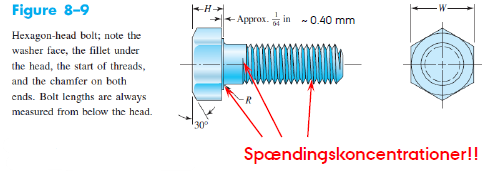

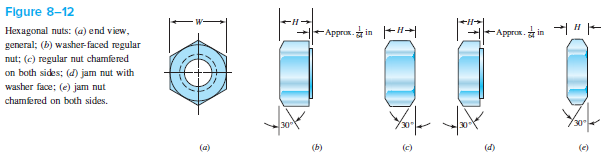

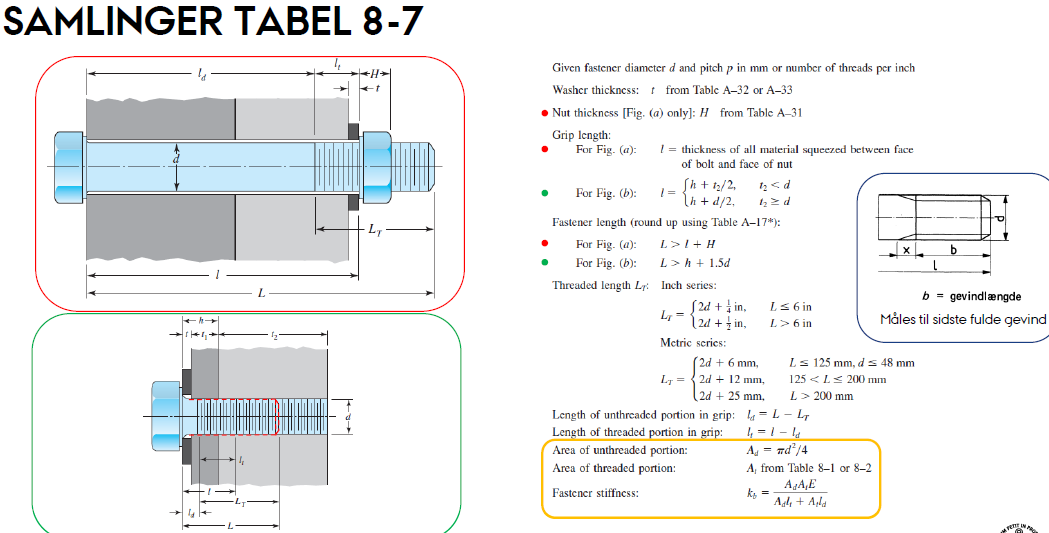

d = 10;             % Nominel diameter (skaft)  [mm]
d_t = (d_r + d_p)/2;    % Træk diameteren
d_w =  21;             % Nøglevidde/Washer face (tabel A-31 se under W)
l =  100; % = t + t = 2*t;    %Klemme længde (regnes kun til midt i underlagets nedre del) [mm]
L = 150;% t + t + H;          % Boltlængde  [mm]
L_T = 130;          % Gevindlængde  [mm] %se også if statment nedenfor
l_d = 30;  % = L - L_T         % Skaft længde  [mm]
l_t = 70;  % = l - l_d         % Gevindlængde i indgreb  [mm]
H_b = 6.85 * u.mm;             % Højde på bolt (se også table A-29) [mm]
H_n = 8.4 * u.mm;             % Højde på møtrik (se også A-31 for møtrikker) [mm]
W = 40;             % Nøglevidde eller washer face se table A-29 [mm]
t = 2;              % tykkelse af pladen [mm]
R = 0.6;              % Rundingsradius (se også table A-29)[mm]
A_t = pi/4 * d_t^2; % Trækspændingsareal (Se tabel 8-1) eller udregn med d_t
A_d = pi/4 * d^2;   % Skaftareal [mm^2]
k_b = 100;          % Boltens stivhed [N/mm]
k_m = 100;          % Underlagets stivhed [N/mm]
C = 2;              % Samlingens stivhedskonstant
E = 207 * u. GPa;   % for stål 207 * u. GPa E-modul, E = 71 * u.GPa; for Alu se tabel (8-8)
alpha = 30 % - trykkegle (mellem 25 og 33 grader, shigley bruger 30 grader) - se også side 17 i bolte 2


%længde af gevind(L_T) følger normalt (8-14)

if separateUnits(L) <= 125 && separateUnits(d) <= 48
    L_T = 2*d + 6 * u.mm
elseif 125 < separateUnits(L) && separateUnits(L) <= 200
    L_T = 2 * d + 12 * u.mm
elseif separateUnits(L) > 200
    L_T = 2 * d + 25 * u.mm
else
    disp("Hmmm something is wrong")
end


%BOLTENS STIVHED
%For stykket uden gevind
% k_d = (A_d * E) / l_d %ligning 8-16

%kan udledes fra
% sigma = F/A
% F = k * delta
% sigma = E * epsilon
% epsilon = Delta L / L = delta / L

% For gevindstykket gælder
% k_t = A_t * E / l_t % ligning 8-16
% 
% % For stykket uden gevind gælder
% k_d = A_d * E / l_d
% k_d = vpa(unitConvert((A_d * E) / l_d, u.MN), 5) %ligning 8-16


%Stivhed for bolten når stykket uden og med gevind lægges sammen sammen
k_b = (A_d * A_t * E) / (A_d * l_t + A_t * l_d)
k_b = vpa(unitConvert((A_d * A_t * E) / (A_d * l_t + A_t * l_d), u.MN), 5) % ligning 8-17


% Stivhed for matrialet
k_m = (pi * E * d * tand(alpha)) /...
    (2 * log(((l * tand(alpha) + d_w - d) * (d_w + d)) / ...
    ((l * tand(alpha) + d_w + d) * (d_w - d)) ) ); %ligning 8 -21

k_m = vpa(unitConvert(k_m, u.MN), 5)



% Stivhed for matrialet med forskellige E-moduler
%ligges sammen til sidst.

%for alu
k_ma =  0.5774 * pi * E_a * d /...
    log( ((1.155 * t_1 + d_w - d) * (d_w + d)) /...
    ((1.155 * t_1 + d_w + d) * (d_w - d)) )

k_ma = vpa(unitConvert(k_ma, u.MN), 5)

d_w_con = d_w + 2 * tand(alpha) * t_1 %forsatte spændings kegle efter alu

k_ms =  0.5774 * pi * E_s * d /...
    log( ((1.155 * t_2/2 + d_w_con - d) * (d_w_con + d)) /...
    ((1.155 * t_2/2 + d_w_con + d) * (d_w_con - d)) ) % her deles t_2 med 2 da det går over midten af spændings keglen

k_ms = vpa(unitConvert(k_ms, u.MN), 5)


% samlet stivhed her med et bidrag fra hvert matriale før peaket af keglen
% og et bidrag fra hvert matriale efter.
k_mtot = vpa(1/(2/k_ma + 2/k_ms), 5)

## YDRE BELASTNING AF FORSPÆNDT SAMLING

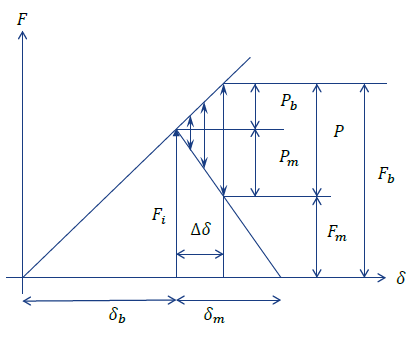

- $F_i$ - forspændingskraft på bolt

- $S_p$ - er proof strength (**table 8-11**) hvis de ikke findes i tabellen $S_p = 0,85 * S_y$

- $\delta_b$ - forlængelse af bolt

- $\delta_m$ - sammentrykning af underlag

- $P$ - ydre last []

- $P_b$ - andel af ydre last der går i bolten

- $P_m$ - andel af ydre last der går i underlaget

- $F_m$ - klemmekraft i underlaget

- $F_b$ - samlet kraft i bolten

- $\Delta \delta$ - forlængelse af bolt fra ydre last

- $\Delta \delta$ - sammenklemning af underlag fra ydre last

$d_w = W$ dette er ofte $d_w = 1,5 \cdot d$ - diameteren af skiven

Fi = 5 * u.kN; % Forspændingskraften
P = 10 * u.kN; % ydre last
d = 10 * u.mm; % spindeldiameteren
p = 1.5 * u.mm; %pitch (afstand fra top til top)
A_r = 52.3 * u.mm^2; %areal fra roddiameter se table 8-1 i shigleys eller one note
d_r = sqrt(4 * A_r / pi);% rod diameteren
d_r_ = vpa(d_r,3)
d_m = (d + d_r)/2; %middeldiameter
d_m_ = vpa(dm,3)

S_p = 380 * u.MPa; %prof strength

d_w = 1.5 * d % hvis ikke andet er opgevet

d_c_min = 10.5 * u.mm; %mindste diameter på spændeskive
d_c_max = 18 * u.mm; %største diameter på spændeskive

d_c =  (d_c_min + d_c_max) / 2;%middel diameter på spændeskive
% d_c = (d + d_w) / 2

f = 0.15; %friktionskoefficienten i gevind
fc = 0.10; %friktionskoefficienten i spændeskive
alpha = 30; %grader %30 grader er den typiske vinkel

n = 1; %antal gevind start
l = p * n; %stigning r omdrejning (l = p ved n = 1)


%%%%%%%%%%%%%%%%%%


Delta_delta = P_b / k_b %forlængelse af bolt
Delta_delta = P_m / k_m %forlængelse af matriale


%Samling stivhedskontanten
C = k_b / (k_b + k_m)


% Spændinger i bolten kan beregnes som
% sigma_b = F_b/A_t

P_b = C * P
sigma_b = (F_i + P_b) / A_t


% Sikkerhed imod flydning

n_p = vpa(unitConvert(S_p / sigma_b, 'SI'), 3) % ligning 8-28
n_p = S_p * A_t / (C*P + F_i)  % ligning 8-28

%seperation så længe forspændingskraften er større end den andel af den ydre last der går i underlaget
% P_m > F_i

P_m = P*(1 - C)

% P = P_b + P_m

n_0 = vpa(unitConvert(F_i / P_m, 'SI'), 3) %sikkerhed

%Hvis n = 1 fås den maximale kraft ved proof spændingen således
F_max = unitConvert(A_t * S_p, u.kN)


% LOAD FAKTOR
n_L = (S_p * A_t - F_i) / (C*P)



% ANBEFALET FORSPÆNDING
F_p = A_t * S_p

F_i = 0.75 * F_p % for IKKE permenente bolte ligning (8-31)
F_i = 0.90 * F_p % for permenente bolte ligning (8-31)


%hooks lov
% k = F/delta
k = A*E/L

% forlængelse
% delta = F * L / (A * E)
delta = F_i * (A_d * l_t + A_t * l_d) / (A_d * A_t * E)



lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind
vpa(lambda);

%funktion for forspændingsmomentet
T = (F_i * dm/2) * ((tan(lambda) + f * secd(alpha)) /...
    (1 - f * tan(lambda) * secd(alpha))) + (F_i * fc * d_c)/2;
T_ = vpa(unitConvert(T, u.N * u.m), 4)


%simpel metode ligning 8-27 eller bolt 3 side 21
% I det tilfælde af at de to 𝑓 og 𝑓𝑐 = 0,15 ender det med at 𝐾 = 0.2
T_simpel = 0.2 * F_i * d; %den reducered formel når d_c = 1.25 * d

T_simpel_ = vpa(unitConvert(T_simpel, u.N * u.m), 4)
if f > separateUnits(tan(lambda)) %konverter fra symbol til numeric
    disp("Den er selvlåsende")
end

## Nyttige figurer til bolte og møtrikker

**Skruesamling**

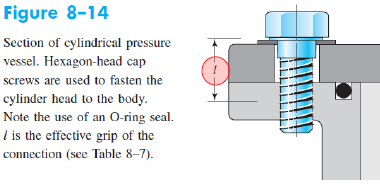

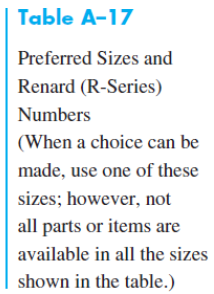

Tabel A-17 anviser hvilke tilgængelige længder der kan anvendes hvis man får en "Skæv længde"

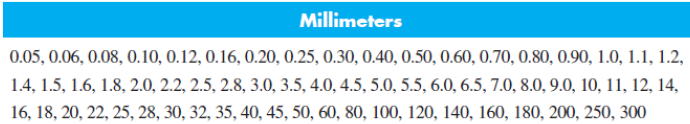

En ideel boltelængde har et par gevind rynker synlig uden for møtrikken!

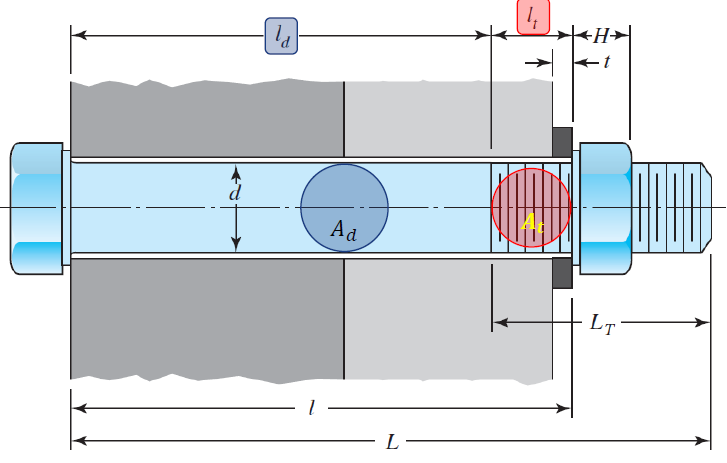

Tryk reglen, vinklen er $\alpha$ -- se også Formel (8-19) som er udledt i kapitel 8-5 eller side 20 i bolte 2

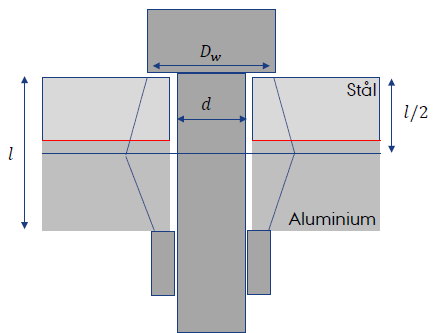

## Forspændingsmoment $T$

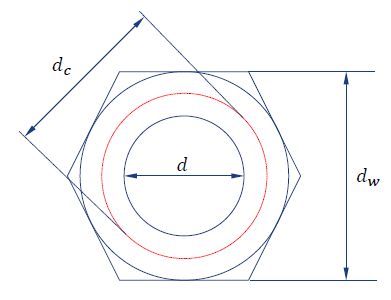

# SAMLINGER MED PAKNINGER

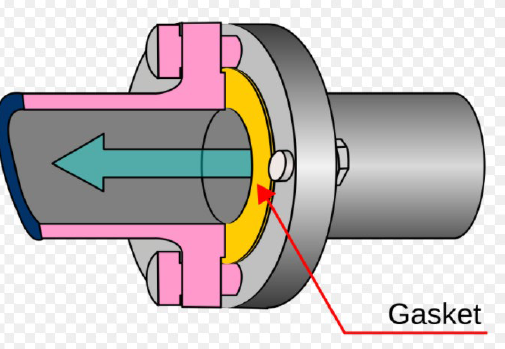

- $N$ - antal bolte

- $d$ - skaftdiameteren på boltene [mm]

- $D_b$ - bolt diameter [mm]

- $p_g$ - pakningstrykket [N/mm^2]

- $A_g$ - Paknings areal - husk at trække bolt hullerne fra [mm^2]

- $F_m$ - klemmekraften pr bolt [N]

- $F_b$ - samlet kraft i bolten [N]

- $P$ - ydre last på pakning [N] eller [bar]

- $C$ - Samlingens stivhedskonstant

N = 18; %M12 bolte 8.8

d_y = 250 * u.mm; % ydre diameter
d_i = 200 * u.mm; % indre diameter
D_b = (d_y + d_i)/2; %bolt cirkel diameteren

d = 12 * u.mm; %skaftdiameteren på boltene %M12

A_g = pi/4 * (d_y^2 - d_i^2 - N * d^2); % Arealet af pakningen% her trækkes bolt arealet af boltene fra (N * d^2).
A_g_ = vpa(A_g,5)

Sut = 800 * u.MPa; % Brud styrken
Sy = Sut * 0.8 * u.MPa; % Flyde spændingen
% Sp = 0.85 * Sy % bolte 3 % udregnet

Sp = 600 *u.MPa; %0.85 * Sy; % tabel 8-11 i shigleys eller onenote

$$A\_g\_ = 15636.0\,{\mathrm{mm}}^{2}$$


A_t = 84.3 * u.mm^2; %opslag i tabel 8.1 i shigleys

F_p = Sp * A_t %forspænding
% Fp_ = vpa(unitConvert(Fi, u.kN))

F_i = 0.75 * F_p
F_i_ = vpa(unitConvert(F_i, u.kN),3)
A_i = pi * (d_i/2)^2
P = 6*u.bar * A_i; % udfra kommende tryk

$$F\_p = 50580\,\mathrm{MPa}\,{\mathrm{mm}}^{2}$$

vpa(unitConvert(P, u.kN), 4)
P_bolt = P/N; %Ekstern last pr bolt
P_bolt_ = vpa(unitConvert(P, u.kN), 4)

$$F\_i = 37935\,\mathrm{MPa}\,{\mathrm{mm}}^{2}$$

n = 1.5; %load factor

$$F\_i\_ = 37.9\,\mathrm{kN}$$

$$A\_i = 10000\,\pi \,{\mathrm{mm}}^{2}$$

k_b = 1 * u.MN * u.mm; %boltens stivhedsfaktor
k_m = 3 * u.MN * u.mm; %underlagets stivhedsfaktor

$$ans = 18.85\,\mathrm{kN}$$


C =  k_b/(k_b + k_m); %stivhedsfaktoren

$$P\_bolt\_ = 18.85\,\mathrm{kN}$$


% F_m = F_i - n*P_bolt * (1-C)
F_m = vpa(unitConvert(F_i - n*P_bolt * (1-C), u.MPa), 3) % klemme kraften

% F_m * N = p_g * A_g
p_g = F_m * N / A_g;  % Pakningstrykket isoleres
p_g_ = vpa(unitConvert(p_g, u.bar), 5)


# FORSKYDNINGSBELASTEDE BOLTE

- $F$ - Snitkraften [N]

- $A_t$ - tværsnitsarealet af bolten [mm^2]

- $A_p$ - Projicerede område af bolten / emnet [mm^2]

- $t$ - Tykkelsen af det tyndeste område [mm]

- $d$ - boltdiameter [mm]

- $\mu$ - Friktionskoefficent mellem pladerne

d = 10; %boltdiameter 

$$F\_m = 0.0368\,\mathrm{MPa}\,m^{2}$$

F = 10; %snitkraft 
A_tau = pi/4 * d^2; %tværsnitsarealet af bolten 
A_p = t * d; % Projicerede område af bolten / emnet


$$p\_g\_ = 423.15\,\mathrm{bar}$$

S_y =  %flydespænding af emne
S_sy = 0.577 * S_y %hmmm


%forskydningsspændninger
tau = F/A_tau

%Fladetryk
% sigma = F/A_p
sigma_b = F/A_p

Invalid expression. Check for missing or extra characters.

sigma_e = F/A_p


%sikkerhed faktorer
% Forskydning på bolte:
eta_b = S_sy / tau

%Fladetryk på bolt 
eta_fb = S_y / sigma_b

%Fladetryk på emne
eta_fb = S_y / sigma_e

%sikkerhedsfaktor imod forskydning

if F_m * mu > F_tau
    disp("klemme kraften(F_m) er stører end forskydningskraften(F_tau)")
    F_m * mu
    F_tau
else 
    disp("Klemmekraften er for lille")
end

eta = F_m * mu / F_tau

# DYNAMISKEBOLTESAMLINGERBRUD

## 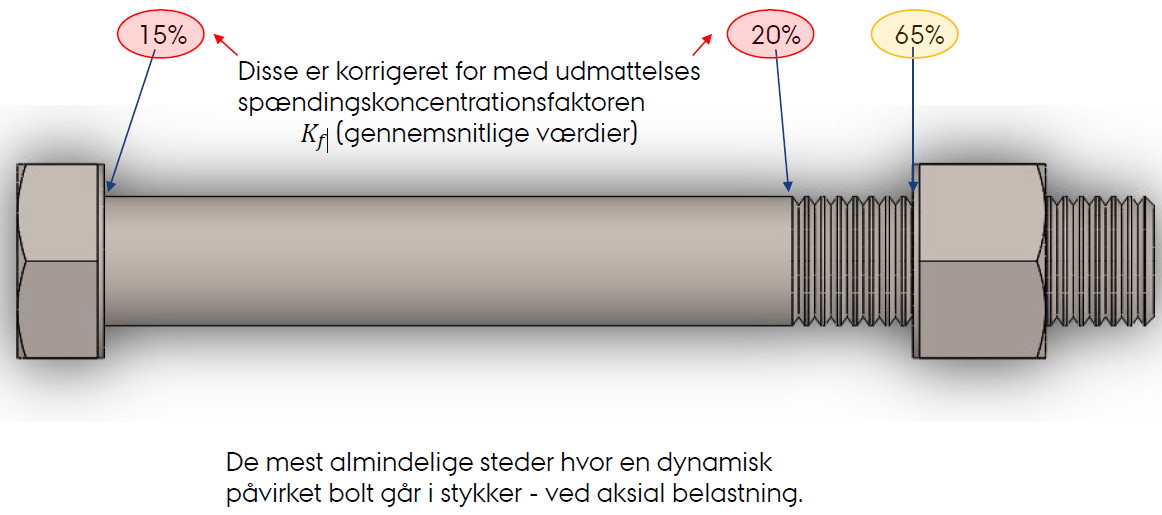

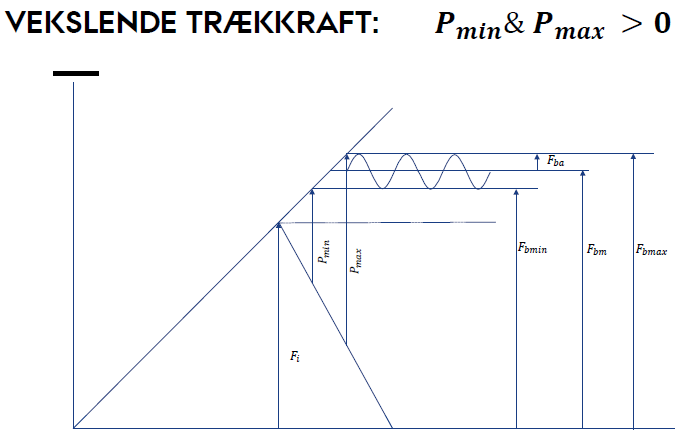

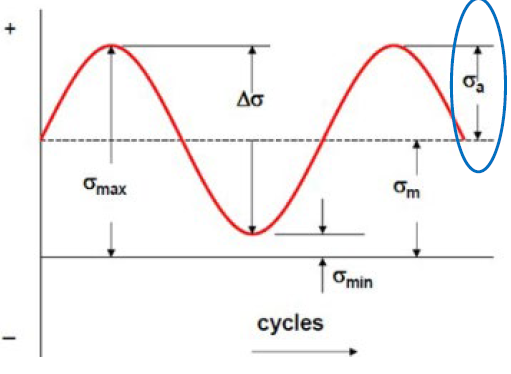

- $S_e$ - Udmattelses styrken (se tabel 8-17) [MPa]

- $S_{ut}$ - Brudstyrke (tabel 8-11) [MPa]

- $K_f$ - udmattelsesspændingskoncentrations-faktoren (se tabel 8-16) [MPa]

- $C$ - Samlingens stivhedskonstant

- $k_b$ - Boltens stivhed [N/mm]

- $k_m$ - Underlagets stivhed [N/mm] - se også side 20 og frem i bolte 2 slides

- $F_i$ - Forspændingskraft på bolt [N]

- $P_{min}$ - Minimum ekstern belastning [F] eller [bar]         **1bar = 0.1 MPa**

- $P_{max}$ - Maksimum ekstern belastning [F] eller [bar]

- $\sigma_a$ - maximal amplitude spændingen

F_i = ;% Forspændingskraft på bolt 
k_b = ;% Boltens stivhed 
k_m = ;% Underlagets stivhed
P_min = ;%Minimum ekstern belastning
P_max = ;%Minimum ekstern belastning


C = k_b / (k_b + k_b) % Samlingens stivhedskonstant
F_bmin = C * P_min + F_i
F_bmax = C * P_max + F_i


% udmattelses spændninger
% Amplitudespænding
% sigma_a = (sigma_max - sigma_min) / 2     %ligning 8-35
sigma_a = ((F_bmax - F_bmin) / 2) / A_t
% sigma_a = C*(P_bmax - P_bmin) / (2*A_t)

% Middelspænding
% sigma_m = (sigma_max + sigma_min) / 2     %ligning 8-36
sigma_m = ((F_bmax + F_bmin) / 2) / A_t
% sigma_m = C*(P_bmax + P_bmin) / (2*A_t) + F_i/A_t


%til goodman diagram
alpha = sigma_a / (sigma_m - sigma_i) %hældningen på last linjen 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Ved særtilfældet P_min = 0  og P_max > 0
% alpha = 1

sigma_a = C* P / (2 * A_t) % %ligning 8-39
sigma_m = C*P / (2 * A_t) + F_i/A_t % %ligning 8-40
% sigma_m = sigma_a + sigma_i %ligning 8-41

% eta_f = S_e*(S_ut - sigma_i) / (sigma_a * (S_ut + S_e)) %ligning 8-45

eta_f = 2 * S_e * (S_ut * A_t - F_i) / (C * P * (S_ut + S_e)) %ligning 8-48


eta_f = S_a / sigma_a
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Uden forspænding bliver C = 1 & F = 0,

% Hvis eta_f / eta_f0 >= 1 så er det fordelagtigt med forspænding

F_i <= (1 - C) * S_ut * A_t  %ligning 8-50


%kontrol for flydning

eta_p = S_p / (sigma_m + sigma_a)

eta_e = S_e* ( S_ut - sigma_i) / (S_ut * sigma_a + S_e * (sigma_m - sigma_i)) 

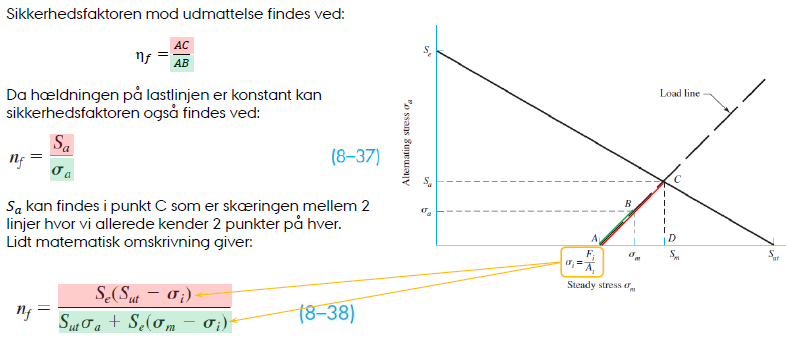

# Brugbare tabeller

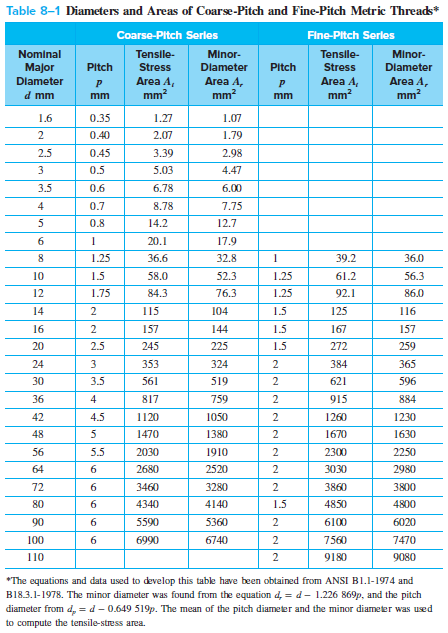

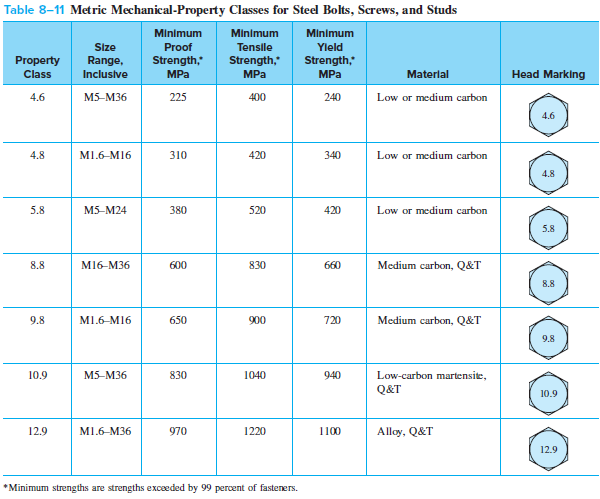

ved 8.8 er der fejl ved size range den går længere ned end M16

Friktionstabeller for $f$ og $f_c$